# Slice Plane Viewer

## Load in data

s2 = load('mristack.mat');

% Place data into a VolumeModel
volModel = wt.model.VolumeModel;
volModel.ImageData = s2.mristack;

% Provide the world coordinates from edge to edge
volModel.WorldExtent = [
    0 300 % Y dimension in mm
    0 300 % X dimension in mm
    0 150 % Z dimension in mm
    ];

## Create the widget

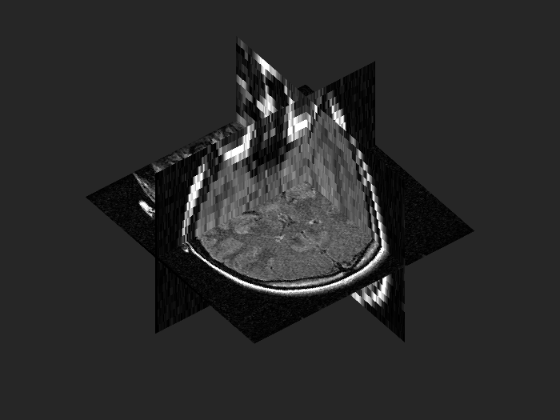

f = uifigure;
g = uigridlayout(f,'ColumnWidth',{'1x'},'RowHeight',{'1x'},'Padding',[0 0 0 0]);
w = wt.SlicePlaneViewer('Parent',g,'VolumeModel',volModel,'Slice',[150 175 10]);movegui(f,'northwest')

movegui(f,'northwest')

## Animate the slices

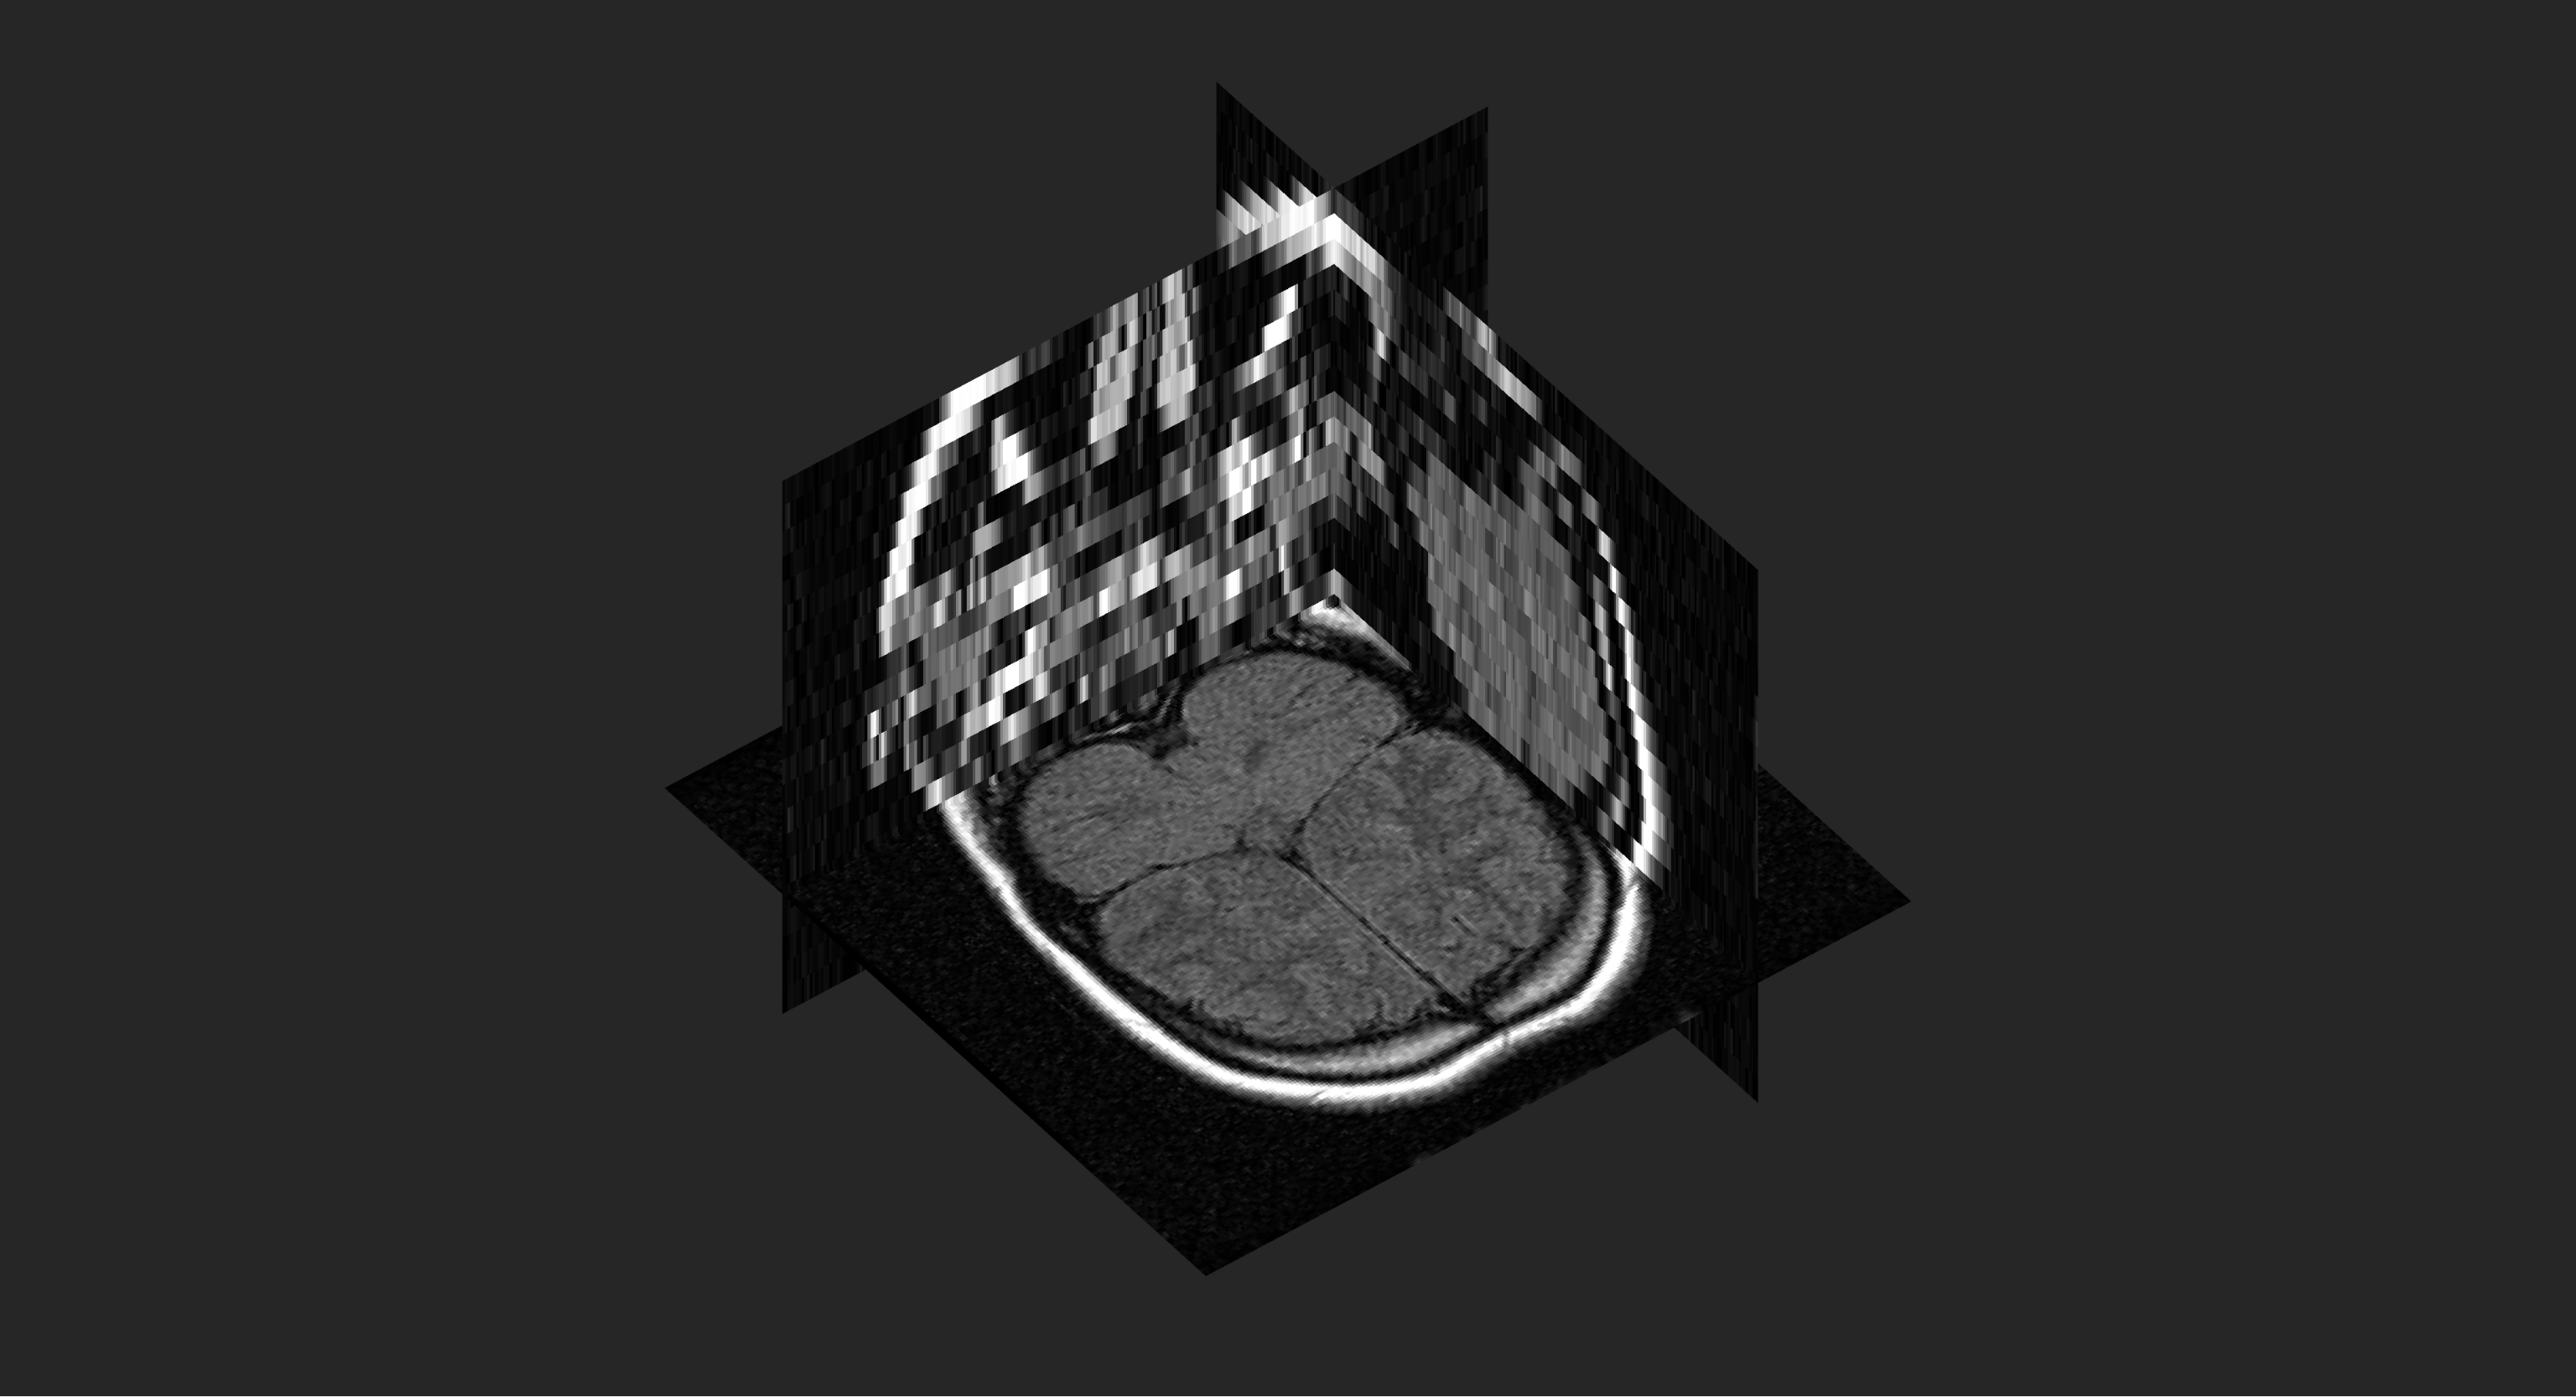

w.Slice = [1 1 5];
for idx = 1:200
   
    w.Slice(1:2) = idx;
    pause(0.01)
    drawnow limitrate    
    
end

*Copyright 2018-2019 The MathWorks, Inc.*